# DDMR Kinematics

[https://www.semanticscholar.org/paper/Controllers-design-for-differential-drive-mobile-on-Contreras-Herrera/02e4ee7a2c7df20833e24977e4fb2eb052186726](https://www.semanticscholar.org/paper/Controllers-design-for-differential-drive-mobile-on-Contreras-Herrera/02e4ee7a2c7df20833e24977e4fb2eb052186726)

[https://www.youtube.com/watch?v=YxuJFQZh94Q](https://www.youtube.com/watch?v=YxuJFQZh94Q)

[https://www.youtube.com/watch?v=RZlZcDxQ8P4](https://www.youtube.com/watch?v=RZlZcDxQ8P4) 

[https://www.scribd.com/document/707050213/DDMR-TRAJECTORY-TRACKING-WITH-USING-PID-AND-KINEMATIC-BASED-BACKSTEPPING-CONTROLLER](https://www.scribd.com/document/707050213/DDMR-TRAJECTORY-TRACKING-WITH-USING-PID-AND-KINEMATIC-BASED-BACKSTEPPING-CONTROLLER) 

[https://arxiv.org/pdf/2202.12391.pdf](https://arxiv.org/pdf/2202.12391.pdf)

[https://www.ncbi.nlm.nih.gov/pmc/articles/PMC9324733/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC9324733/)

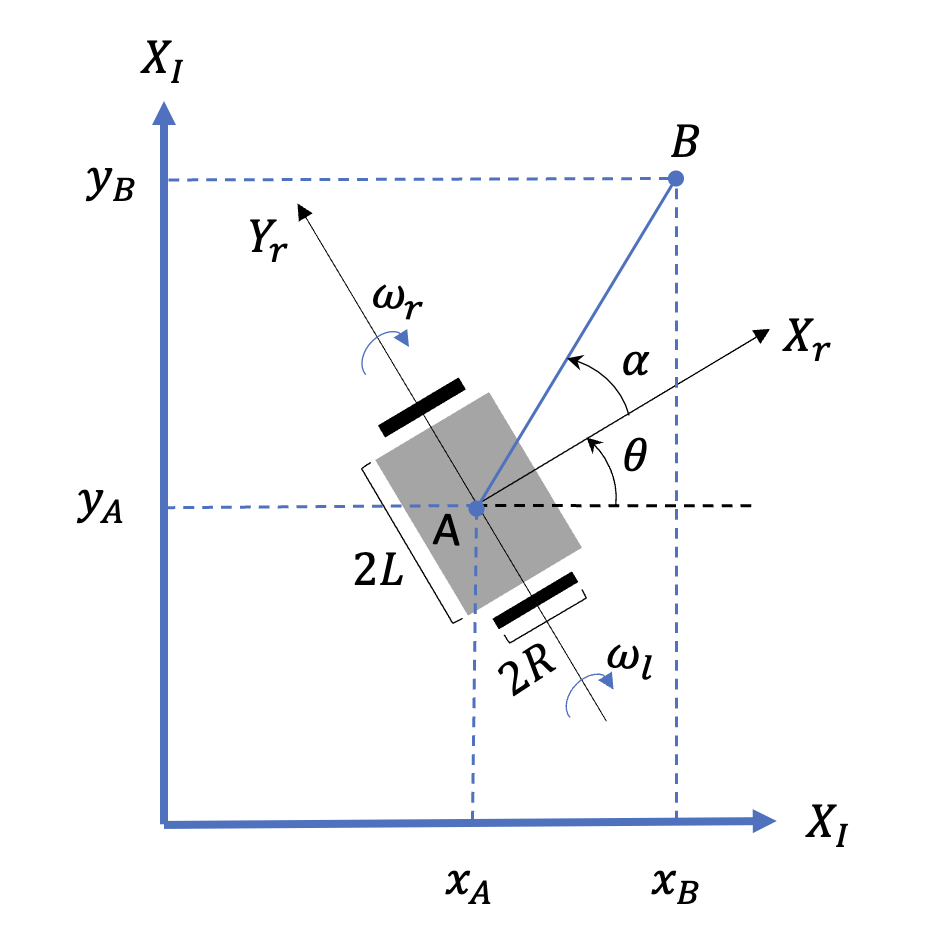

% Model Parameters
L = 0.075;     % Wheel Base 
R = 0.035;    % Wheel Radius m

$\left\lbrace X_{I\;} ,Y_I \right\rbrace$ Inerial Frame

$\left\lbrace X_r \;,Y_r \right\rbrace$ Inerial Frame

$\omega_r \left(t\right)$ Right Wheel angular speed             [rad/s]

$\omega_l \left(t\right)$ Left Wheel angualr speed                [rad/s]

$v_A \left(t\right)$ Body linear velocity                          [m/s]

$\omega_A \left(t\right)$ Body angular velocity                      [rad/s]

$\theta$ Robot heading angle                             [rad]

$x_A$ Body x position in Interial Frame 

$y_A$ Body y position in Intertial Frame

### Forward Kinematics

In Intertial Frame 


$${\dot{q} }_A =\left\lbrack \begin{array}{c}
{\dot{x} }_A \\
{\dot{y} }_A \\
{\dot{\theta} }_A 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{\mathrm{Rcos}\left(\theta \right)}{2} & \frac{\mathrm{Rcos}\left(\theta \right)}{2}\\
\frac{\mathrm{Rsin}\left(\theta \right)}{2} & \frac{\mathrm{Rsin}\left(\theta \right)}{2}\\
\frac{2R}{L} & -\frac{2R}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\omega_r \\
\omega_l 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\cos \left(\theta \right) & 0\\
\sin \left(\theta \right) & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_a \\
\omega_a 
\end{array}\right\rbrack$$
 


$${\dot{q} }_A =\left\lbrack \begin{array}{c}
{\dot{x} }_A \\
{\dot{y} }_A \\
{\dot{\theta} }_A 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v_A \;c\mathrm{os}\left(\theta \right)\\
v_A \;\sin \left(\theta \right)\\
2R\frac{\left(\omega_R -\omega_L \;\right)}{L}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{R}{2}\left(\omega_R +\omega_L \;\right)\;c\mathrm{os}\left(\theta \right)\\
\frac{R}{2}\left(\omega_R +\omega_L \;\right)\;\sin \left(\theta \right)\\
2R\frac{\left(\omega_R -\omega_L \;\right)}{L}
\end{array}\right\rbrack$$


## Inverse Kinematics


$$\left\lbrack \begin{array}{c}
\omega_r \\
\omega_l 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v_a -Lw_a \\
v_a +Lw_a 
\end{array}\right\rbrack$$


$\omega_r$ = $v_A -\omega_A L$

$\omega_l$ = $v_A +\omega_A L$